# TAPAS report

## Task-state data

### Replication effort

First we replication some results from Frässle et al. (2018). This is the paper that introduces sparse rDCM and includes several simulations to evaluate the performance of the method. 

We'll try to replicate the simulations in depicted in Frässle et al. (2018) 1B. . This network is also used in the TAPAS tutorial so it seems to be regarded as a good case study.

What does the task used in the tutorial/simulations in the paper look like? There are 25 inputs with short block stimulations coming on at different time points for the nodes they stimulate. Below they are depicted in five rows for visual clarity.

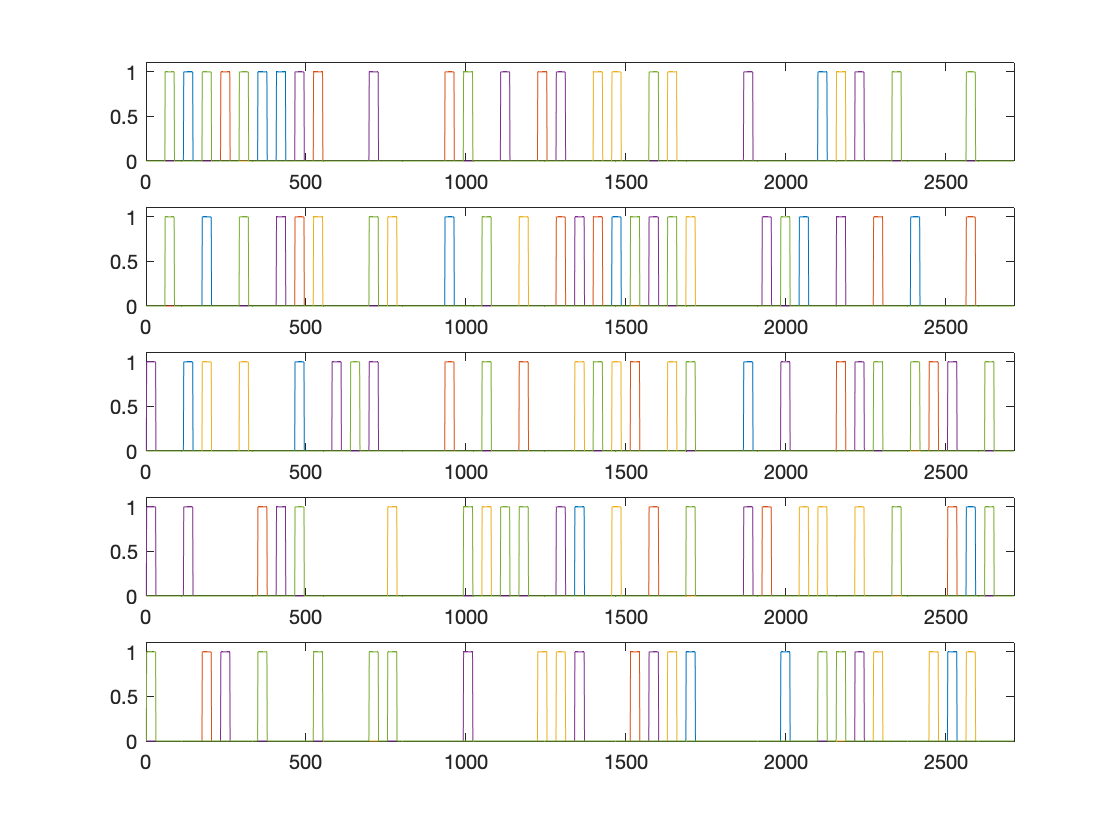

temp = load('tapas-master/rDCM/test/DCM_LargeScaleSmith_model1.mat');
DCM = temp.DCM;
downsampled_task = DCM.U.u(1:16:end,:);

clf
figure
for i=1:5
    subplot(5, 1, i)
    plot(downsampled_task(:, ((i-1)*5+1):(i*5)));
    xlim([0 2714]);
    ylim([0 1.1]);
end

Which nodes does each input stimulate?

Each input stimulates only one node so half of the nodes are not stimulated.

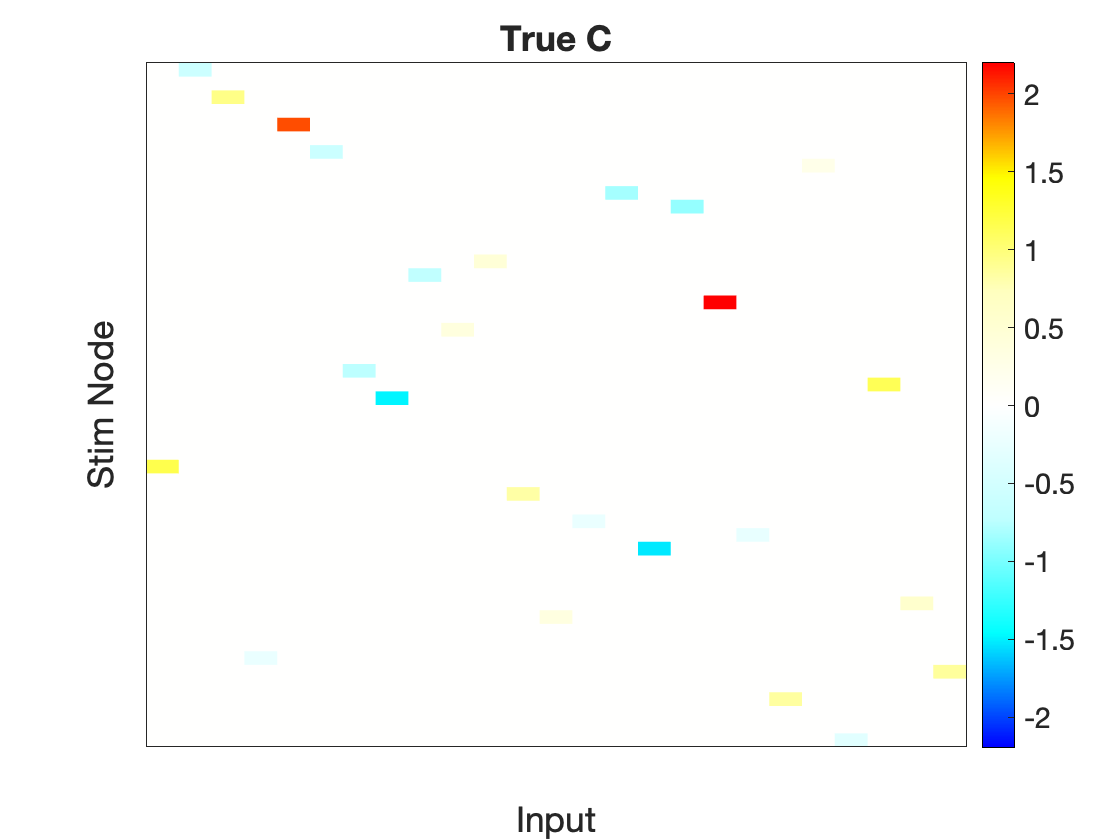

clf
cmap = mycmap();   
h = heatmap(DCM.Tp.C);
h.CellLabelColor = 'none';
h.Colormap = cmap;
col_lims = [abs(min(min(DCM.Tp.C))) abs(max(max(DCM.Tp.C)))];
col_lim = max(col_lims);

h.ColorLimits = [-1*col_lim col_lim];
title("True C"); 
xlabel("Input");
ylabel("Stim Node");
grid(h, 'off');
h.XDisplayLabels = repmat(" ", size(DCM.Tp.C, 2), 1);
h.YDisplayLabels = repmat(" ", size(DCM.Tp.C, 1), 1);
ax = gca;
ax.FontSize = 16;

What does inversion with TAPAS look like?

options.SNR             = 3;
options.y_dt            = 0.5;
options.p0_all          = sum(sum(logical(DCM.Tp.A)))/size(DCM.Tp.A,1)^2;  % single p0 value close to true sparsity (for computational efficiency)
options.iter            = 100;
options.filter_str      = 5;
options.restrictInputs  = 1;

% run a simulation (synthetic) analysis
type = 's';
DCM = tapas_rdcm_generate(DCM, options, options.SNR);


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 1/1
Processing region: 50/50
Finalize results


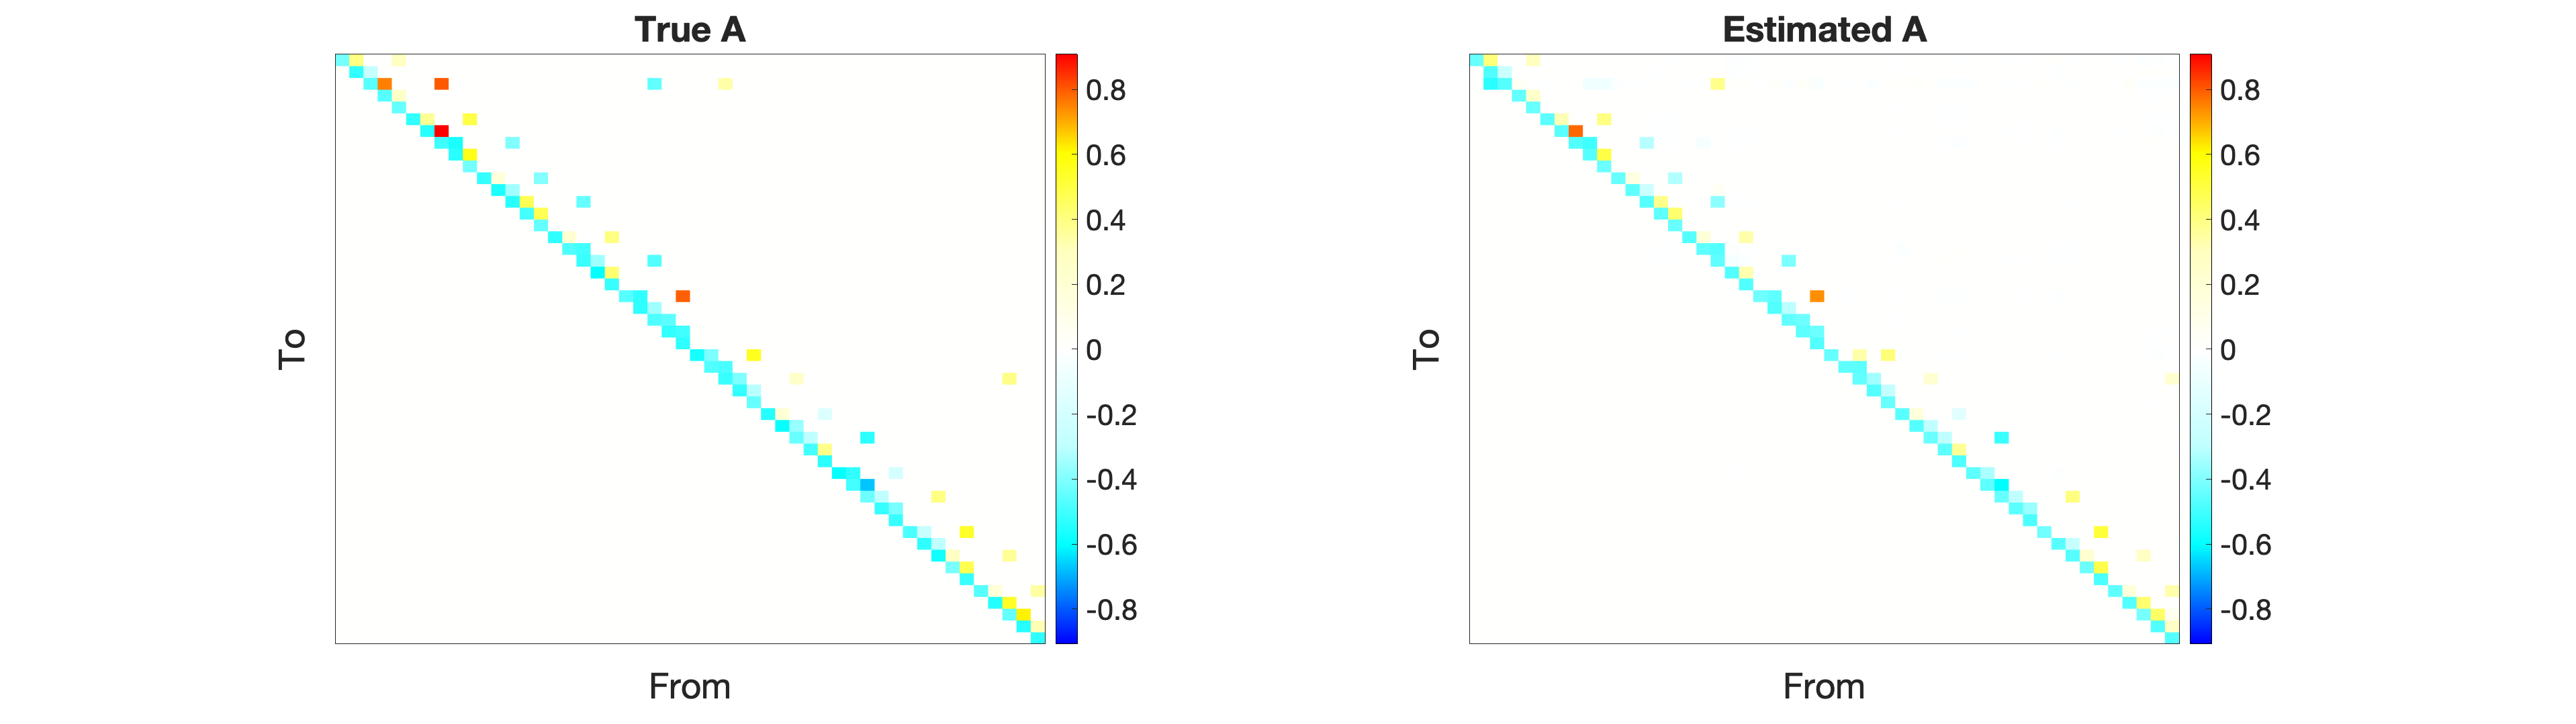

[output, options] = tapas_rdcm_estimate(DCM, type, options, 2);
plot_true_est_connectivity(DCM, output, 1);

The estimation appears good but this visualization might be misleading because the diagonals that have strong priors around their true values are recovered well but it's not very clear how bad the off-diagonal estimates are.

What does the difference matrix look like?

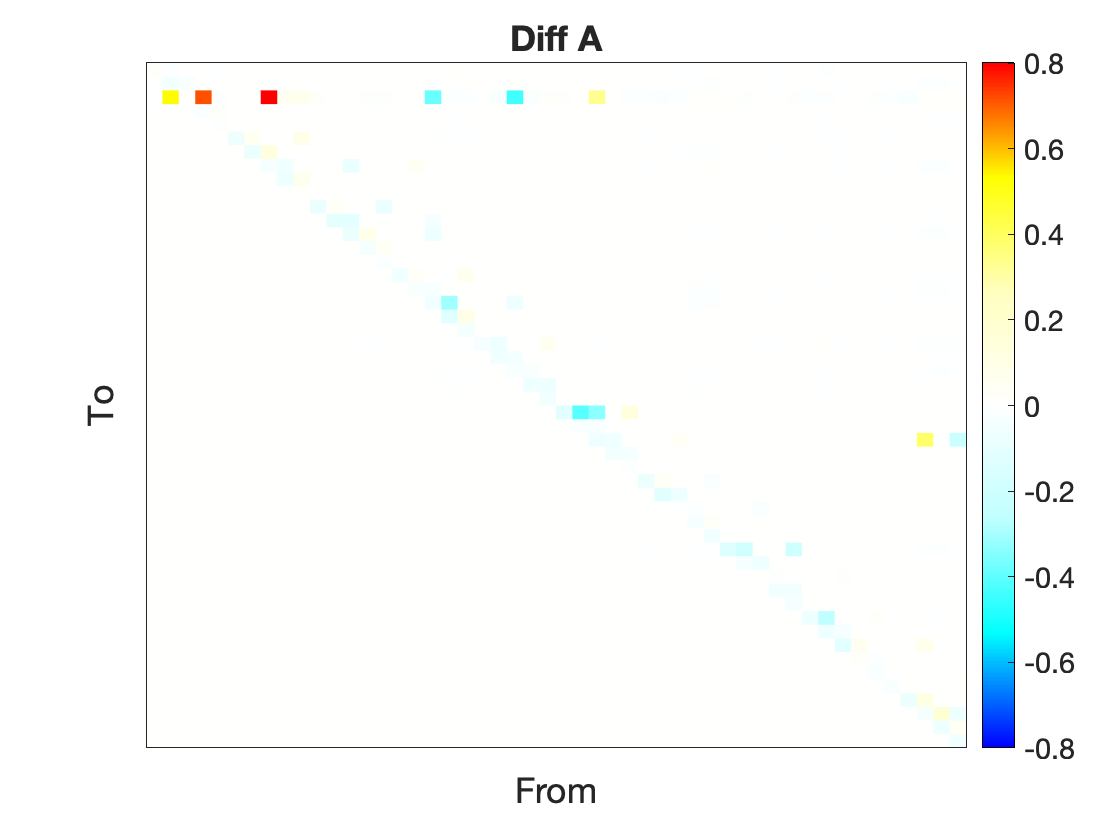

diff_A = DCM.Tp.A - output.Ep.A;
clf
figure
plot_connectivity(diff_A);
title("Diff A"); 
ax = gca;
ax.FontSize = 16;

What is the RMSE for the non-zero off-diagonal connections?

diff_A_upper = triu(diff_A,1);
non_zeros_edges = triu(logical(DCM.Tp.A),1);
sqrt(mean(diff_A_upper(non_zeros_edges).^2))

ans = 0.1906

What is the average absolute difference for the non-zero off-diagonal connections?

ans = 0.1098


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 1/1
Processing region: 50/50
Finalize results


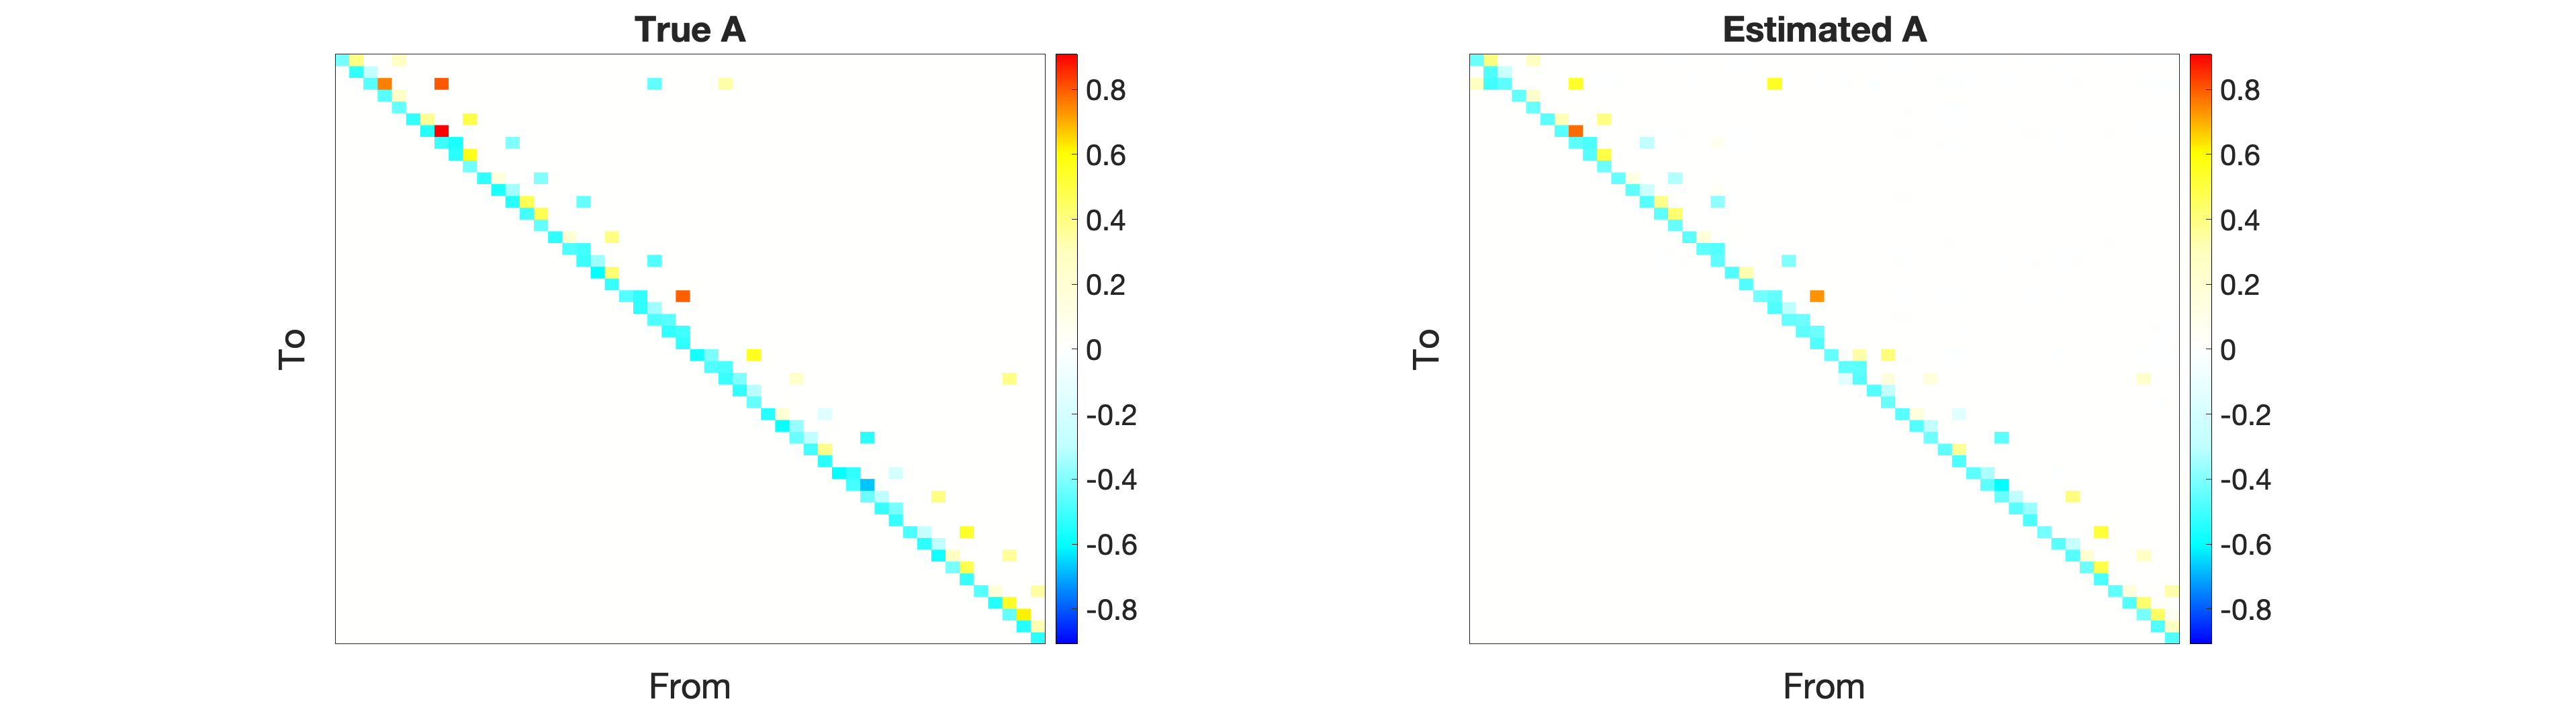

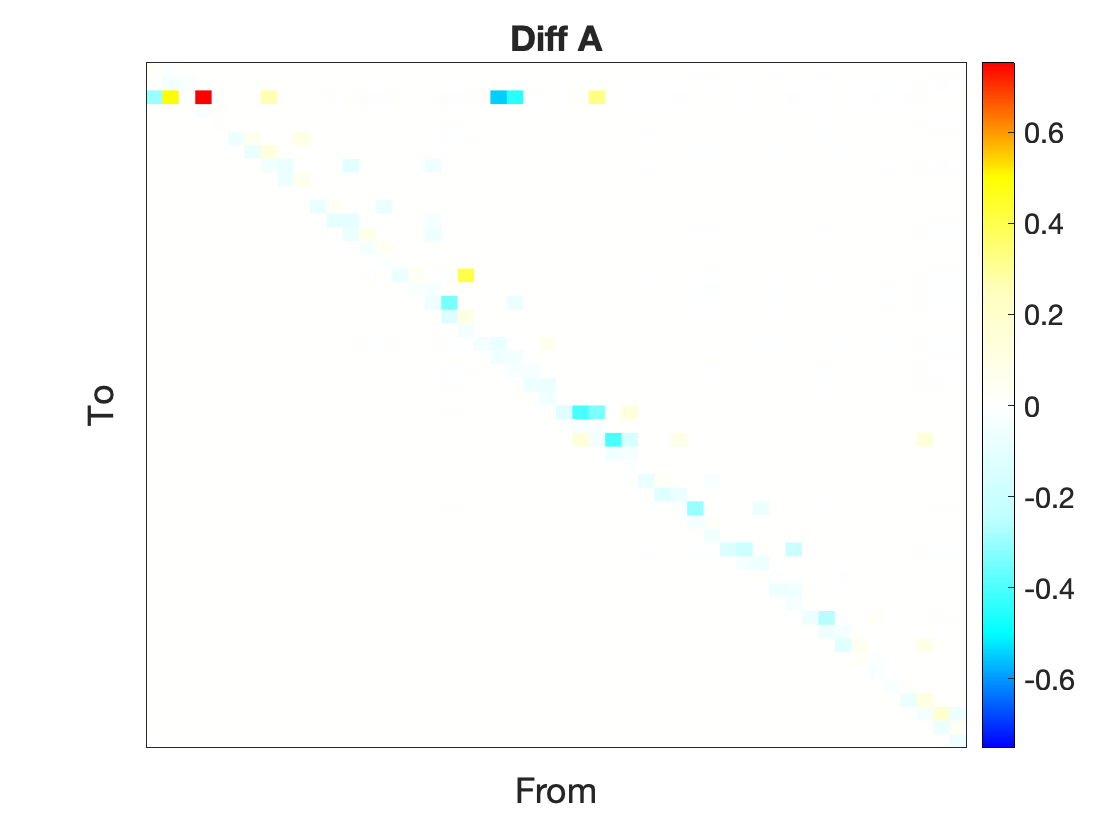

ans = 0.1823

ans = 0.1170

mean(abs(diff_A_upper(non_zeros_edges)))

Though both the paper and we so far focused on the recovered parameters a standard model evaluation fit would be to compare the predicted signal to the actual signal.

In the context of rDCM the DV used for estimation is the derivative of each node's activity in the frequency domain. 

What does the predicted versus actual signal look like? Magnitude spectrum plots for the actual and predicted derivatives in the frequency domain for the first 5 nodes.

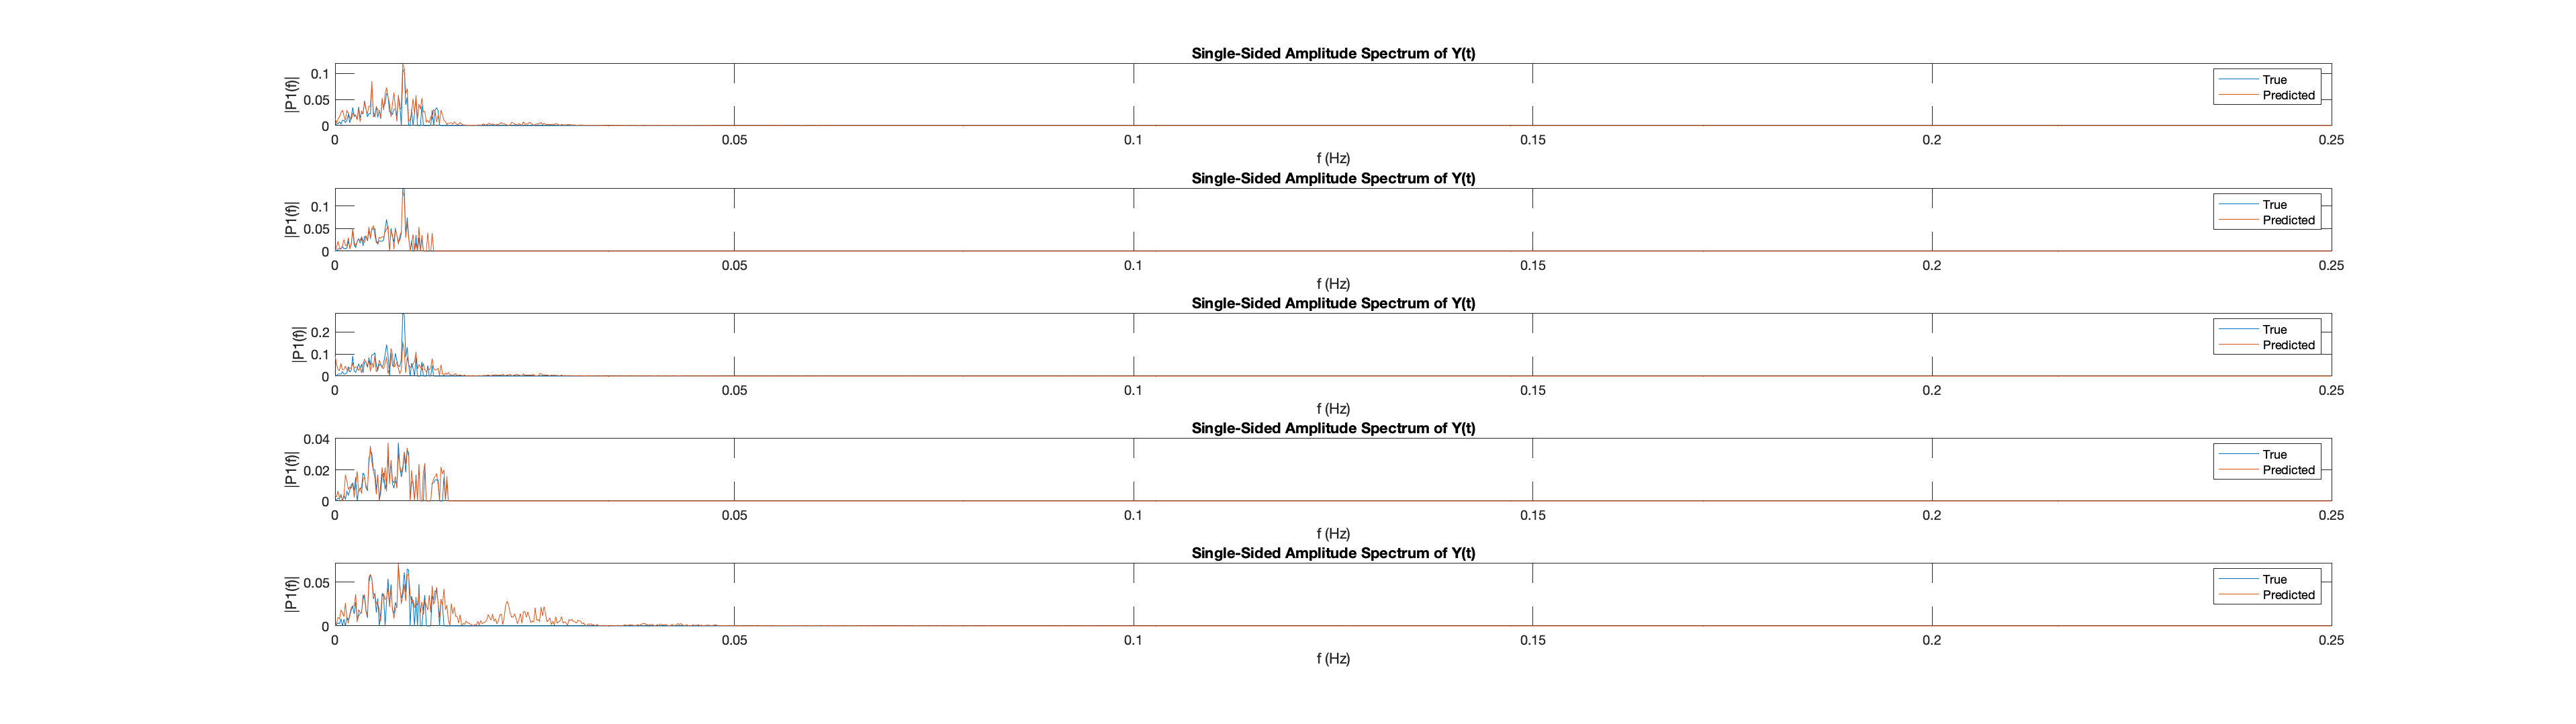

plot_pred_vs_actual(DCM, output, 5, 1)

The model is fit in the frequency domain but just to get a sense of how things differ in the time domain

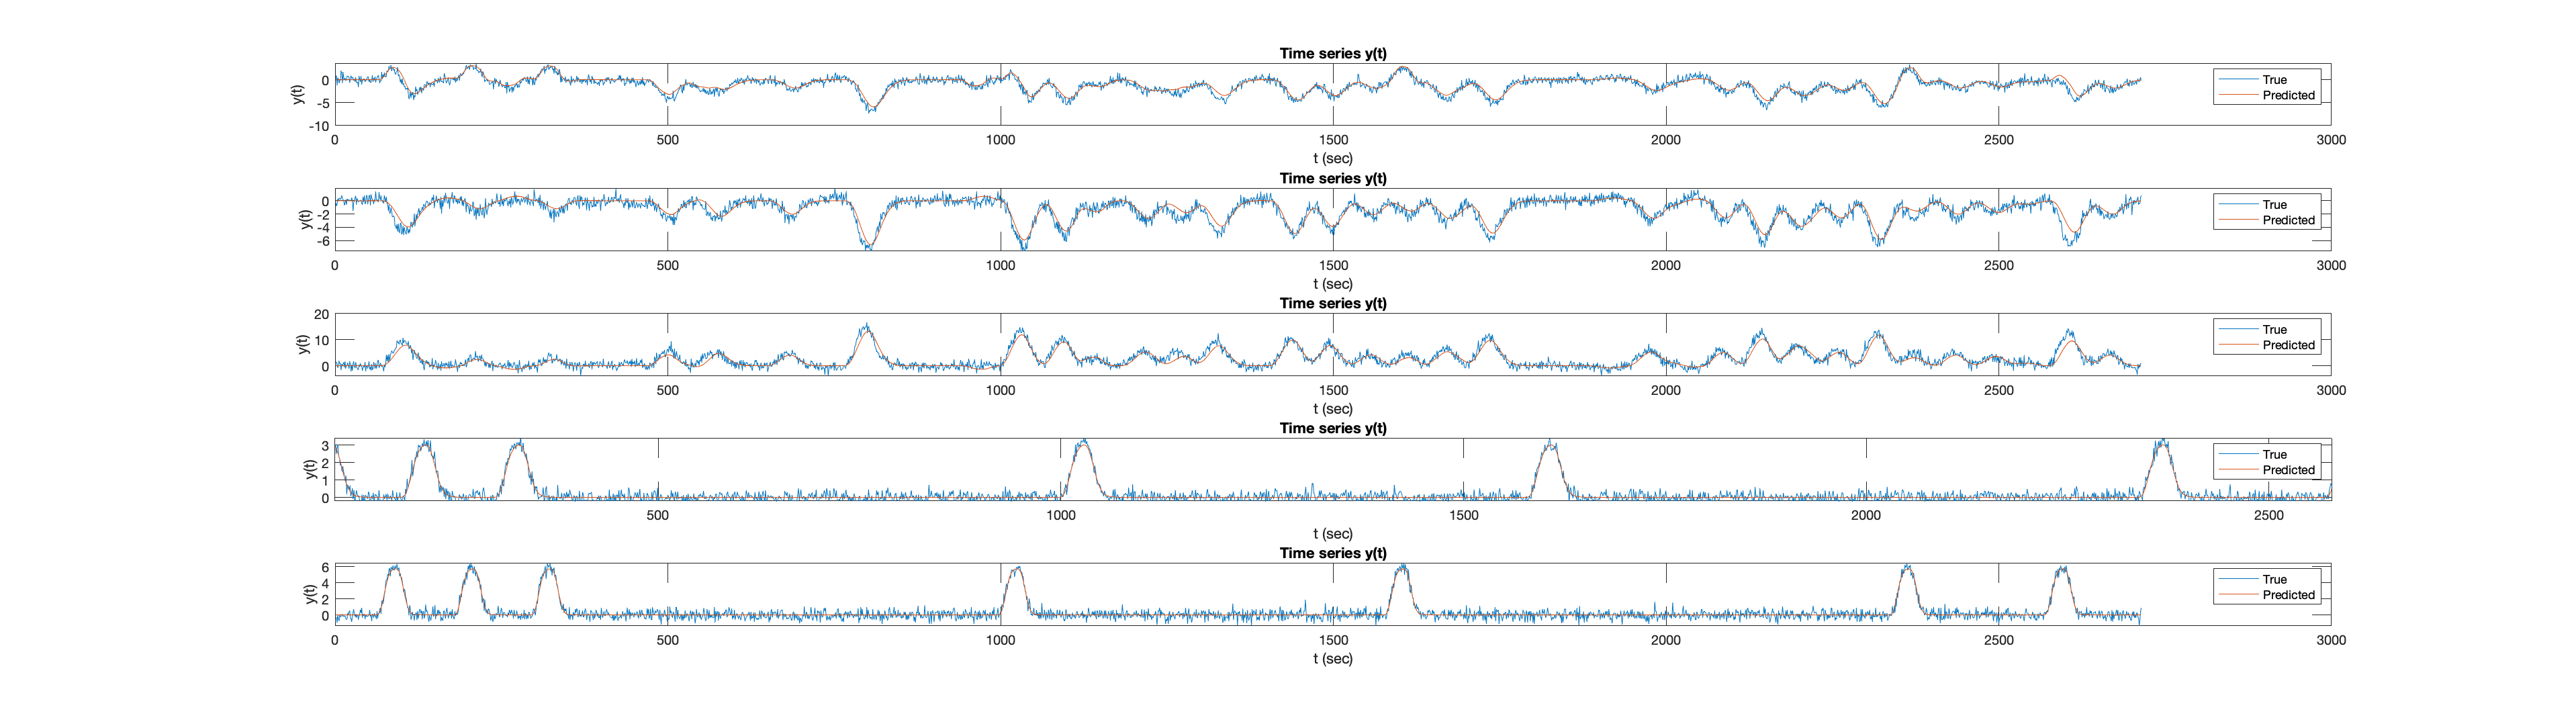

plot_pred_vs_actual(DCM, output, 5, 0)

### New simulations

Three node network that looks like:

#### Task timing effects

#### Network size effects

#### Predicting vs actual output

## Resting-state

### Replication effort

Frässle et al. (2021) models in figure 1A and outputs in figure 3A

### New simulations

Three node network that looks like:

#### Predicting vs actual output